%clear;clc;
V=1;
position=[0 0 0;0 0 0];
velocity=[0 0 0;0 0 0];
mass=1;
I=[1 1 1];
delta_t=1;

s=Submarine();
s.V=V;s.mass=mass;s.I=I;s.position=position;s.velocity=velocity;s.delta_t=delta_t;
s.start_position=position;

s.velocity;
f=[0 1 0;0 0 0];
s.Force(f);
s.velocity;

p=[];
for i=1:2000
    s.update_position();
    p=[p;s.position(1,:)];
    if s.position(1,3)<=0
        s.position(1,3)=0;s.position(2,1)=0;
        s.velocity(1,3)=0;
    end
end
% plot3(p(:,1),p(:,2),p(:,3),'-b')
% grid on %加网格
% axis square %命令坐标为方形

clear;clc;
V=0.1;
position=[0 0 0;0 0 0];
velocity=[0 0 0;0 0 0];
mass=1;
I=[1 1 1];
delta_t=0.01;
s=Submarine();
s.V=V;s.mass=mass;s.I=I;s.position=position;s.velocity=velocity;s.delta_t=delta_t;
s.start_position=position;

rho=1;e_velocity=[1 0 0];C=1;A=1;
e=environment();
e.A=A;e.rho=rho;e.velocity=e_velocity;e.position=[];e.C=C;e.A=A;

p=position;
v=velocity;
for t=1:delta_t:20
    s.update_position();
    s.Force(get_force(s,e));
    if s.position(1,3)<=0
        s.position(1,3)=0;s.position(2,1)=0;
        s.velocity(1,3)=0;
    end
    p=[p;s.position(1,:)];
    v=[v;s.velocity(1,:)];
end
% plot3(p(:,1),p(:,2),p(:,3),'-b')
% grid on %加网格
% axis square %命令坐标为方形
% figure(2)
% plot3(v(:,1),v(:,2),v(:,3),'-r')
% grid on %加网格
% axis square %命令坐标为方形
% figure(4)
% plot(v(:,1))

%假定搜索海域
clear;clc;
l=8000;w=6000;h=4000;
lenth=100;

ln=ceil(l./lenth);wn=ceil(w./lenth);hn=ceil(h./lenth);
e(ln,wn,hn+1)=environment;
[x,y,depth]=get_depth([ln wn]);
depth=depth.*20;
ae_velocity=[0.12 -0.19 0.02];v_amp=0.1;
atemp=30;temp_amp=3;

for i=1:ln
    for j=1:wn
        for k=1:hn+1
%             if isnan(e(i,j,k).position)
%                 continue
%             end
            position=[(i-1).*lenth (j-1).*lenth (k-1).*lenth];
%             if depth(i,j)<=position(3) || isnan(depth(i,j))
% %                 e(i,j,k+1).position=NaN;
%                 continue
%             end
            
            temp=0;e_velocity=[0 0 0];
%             e_velocity=ae_velocity+v_amp.*randn([1,3]);
%             temp=atemp+temp_amp.*randn();
            e(i,j,k).position=position;
            [rho,C]=environment_parameters(temp,(k-1).*lenth);
            e(i,j,k).rho=rho;
            e(i,j,k).C=C;
            e(i,j,k).lenth=lenth;
            e(i,j,k).velocity=e_velocity;
        end
    end
end

V=14.8;
position=[5000 3000 30;10 20 30];
velocity=[2 3 -1;0 0 0];
mass=6.519e3+8.7e3;
I=[15.451e3 6.712e3 15.451e3];
delta_t=1;
s=Submarine();
s.V=V;s.mass=mass;s.I=I;s.position=position;s.velocity=velocity;s.delta_t=delta_t;
s.start_position=position;

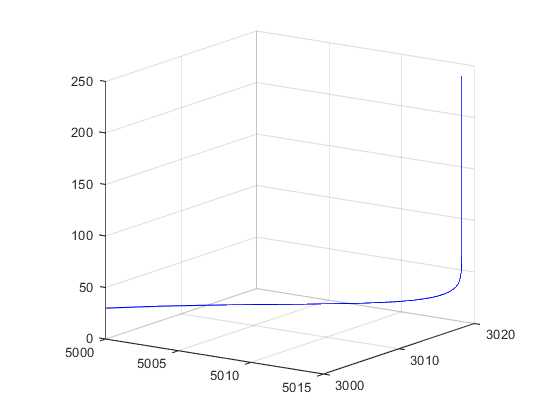

p=position(1,:);
v=velocity(1,:);
etime=500;
for t=0:delta_t:etime
    [x_index,y_index,z_index]=get_position(s.position(1,:),lenth);
    if s.position(1,3)<=0
        s.position(1,3)=0;s.position(2,1)=0;
        s.velocity(1,3)=0;
    end
    if depth(x_index,y_index)<=s.position(1,3)
        s.position(1,3)=depth(x_index,y_index);s.position(2,1)=0;
        s.velocity(1,3)=-0.001.*s.velocity(1,3);
%         break
    end
    s.update_position();
    s.Force(get_force(s,e(x_index,y_index,z_index)));
    p=[p;s.position(1,:)];
    v=[v;s.velocity(1,:)];
end
t=linspace(0,etime,2+etime./delta_t);
plot3(p(:,1),p(:,2),p(:,3),'-b')
grid on %加网格
axis square %命令坐标为方形

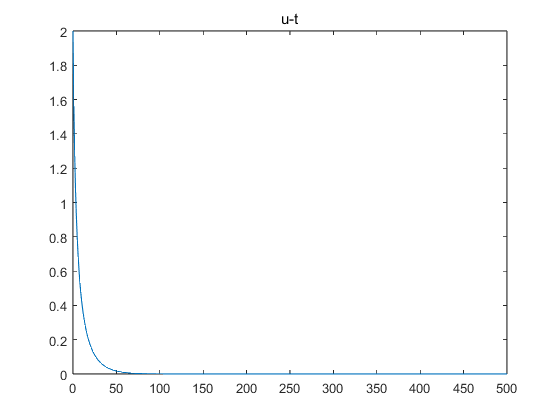

% figure(2)
% plot3(v(:,1),v(:,2),v(:,3),'-r')
% grid on %加网格
% axis square %命令坐标为方形

figure;
plot(t,v(:,1))
title("u-t");

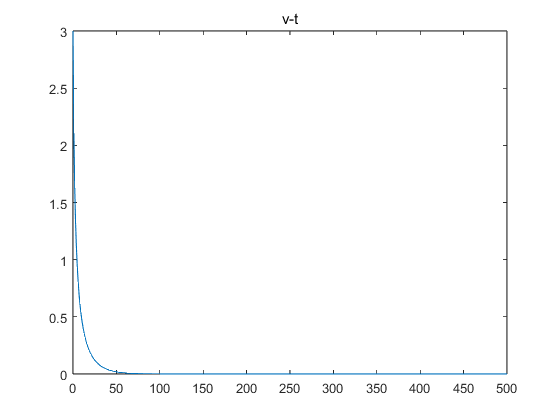

figure;
plot(t,v(:,2))
title("v-t");

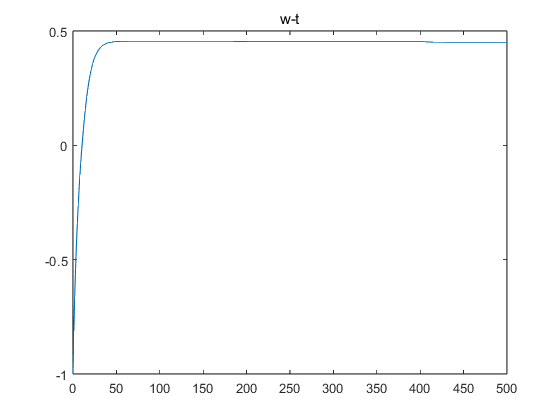

figure;
plot(t,v(:,3))
title("w-t");

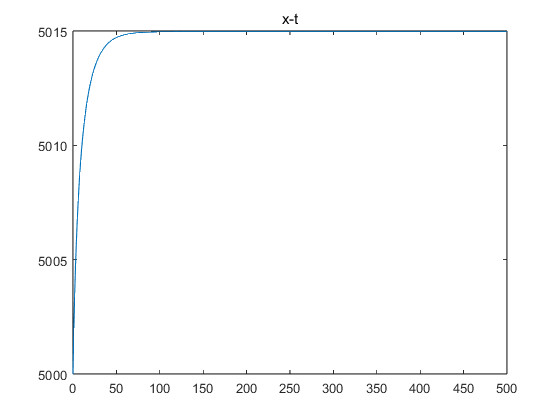


figure;
plot(t,p(:,1))
title("x-t");

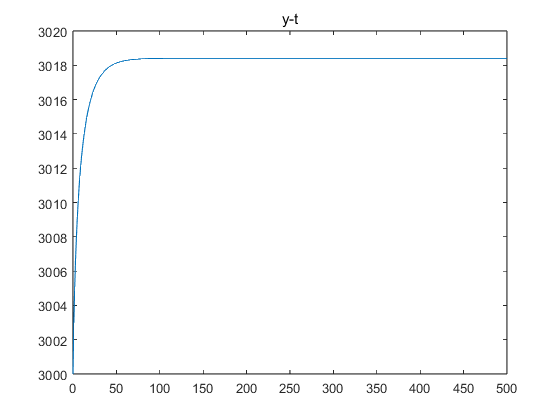

figure;
plot(t,p(:,2))
title("y-t");

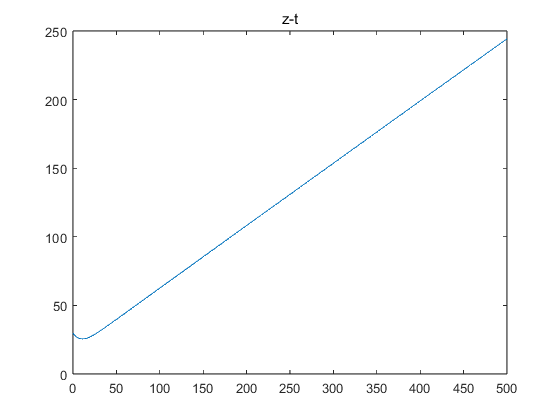

figure;
plot(t,p(:,3))
title("z-t");